# Raíces de ecuaciones en una variable

### Problema

Considere la pared de un horno de $\Delta {\;}_x$ de espesor, la temperatura del lado interno es $T_0$, si las pérdidas de calor desde la superficie externa se producen por convección y radiación, se desea determinar la temperatura $T_1$ del lado externo de la pared. La ecuación que rige esta situación problemática es:


$$\frac{k}{\Delta_x }\left(T_1 -T_0 \right)+\epsilon \sigma \left(T_1^4 -T_f^4 \right)+h\left(T_1 -T_f \right)=0$$


Para este problema considere los siguientes datos:

- Conductividad térmica: $k=1,33W/\textrm{mk}$.

- Emisividad: $\epsilon \;=0,8$.

- Temperatura del lado interno de la pared: $T_0 =642\;K$.

- Temperatura del lado externo de la pared: $T_1$.

- Temperatura del aire: $T_f =299\;K$.

- Coeficiente convectivo de transferencia calórica: $h=18W/m^2 K$.

- Constante de Stefan-Boltzmann: $\sigma =5,67\times {10}^{-8} W/m^2 K^4$.

- Espesor de la pared: $\Delta_x =0\ldotp 08m$.

Elija adecuadamente los valores iniciales para los métodos y determine la temperatura $T_1$ del lado externo de la pared.

Solución:

Observe que al sustituir los datos que se brindan en el problema se tiene que:


$$\frac{1,33}{0,08}\left(T_{\;1} -642\right)+0,8\cdot 5,67\times {10}^{-8} \;\left(T_1^4 -{299}^4 \right)+18\left(T_1 -299\right)=0$$


la cual en su forma más simple corresponde a:


$$4,56{\times 10}^{-8} T_1^4 +34,625T_1 -16366,79156=0$$


Observe que la gráfica de la función está dada:

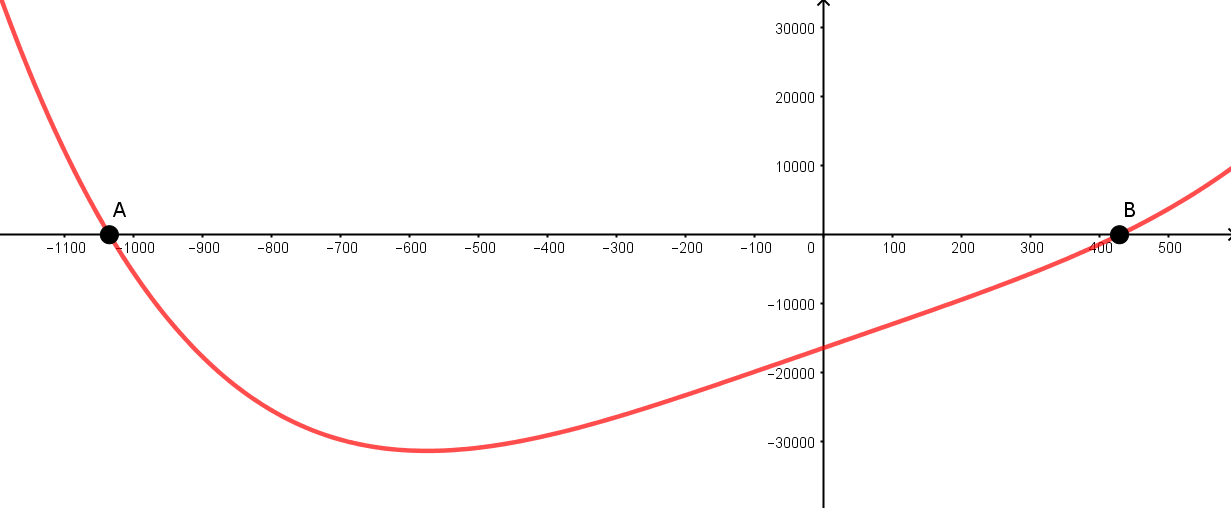

De lo anterior, es posible observar que hay dos ceros para la función. Considerando que la variable dependiente $T_1$ en este caso hace referencia a la temperatura del lado externo de la pared por lo que debemos considerar el valor positivo que se muestra en la gráfica. Por esta razón y para efectos de este problema se consideran como valores inicial $a$ y final $b$ del intervalo donde se quiere hallar el cero, 100 y 500 respectivamente. Observe que en este intervalo se cumple la condición de cambio de signo y además existe la solución buscada. 

Para dar solución a este problema se hará uso de "**Toolbox en Matlab para métodos numéricos**" creado en este proyecto.

Como primer paso, se debe ingresar la función en el recuadro llamado "$f\left(x\right)$" como se muestra en la siguiente imagen:

**NOTA: ** Tenga en cuenta que al ingresar la función, la ecuación debe estar escrita en la forma $f\left(x\right)=0$ y lo que debe ingresar es únicamente $f\left(x\right)$. Además, se debe escribir en función de la variable independiente $x$.

Como segundo paso, se deben indicar los valores inicial y final. Como se mencionó anteriormente, se considerará $a=100$ y $b=500$. Estos valores se deben ingresar en los espacios llamados $\textrm{"a"}$ y $\textrm{"b"}$ como se muestra en la siguiente imagen:

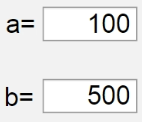

Finalmente se debe indicar la cantidad máxima de iteraciones que se desea ejecutar o el error mínimo aceptable. En este caso se considerará una cantidad máxima de 100 iteraciones y un error máximo de 0.0001. Estos valores se deben ingresar en los espacios llamados $\textrm{"Iteraciones}\;\textrm{máximas"}$ y $\textrm{"Tolerancia"}$ como se muestra en la siguiente imagen:

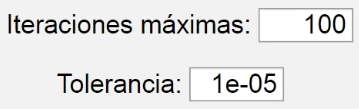

A partir de este momento, solo se debe seleccionar el método con el cuál se desea aproximar la solución de la ecuación ingresada. Puede aproximar dicha solución por medio de los siguientes métodos:

- Bisección.

- Recta Secante.

- Falsa Posición.

- Newton Raphson.

- Punto FIjo.

A continuación se muestra el cómo se visualiza la lista desplegable de estas opciones:

Por defecto aparece seleccionado el método de bisección, sin embargo al hacer clic sobre la pestaña, se despliegan las demás opciones:

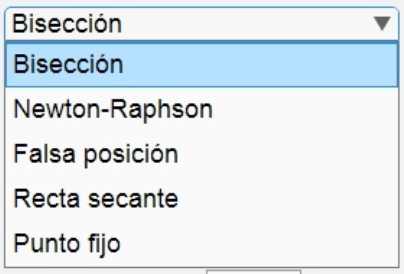

Para calcular dicho resultado, solo debe hacer clic sobre el botón llamado "Calcular":

A continuación se muestran y analizan los resultados obtenidos con cada uno de los métodos:

#### Método de Bisección

- Al seleccionar el método "**Bisección**" y dar clic en el botón "Calcular" la pantalla se visualiza de la siguiente manera:

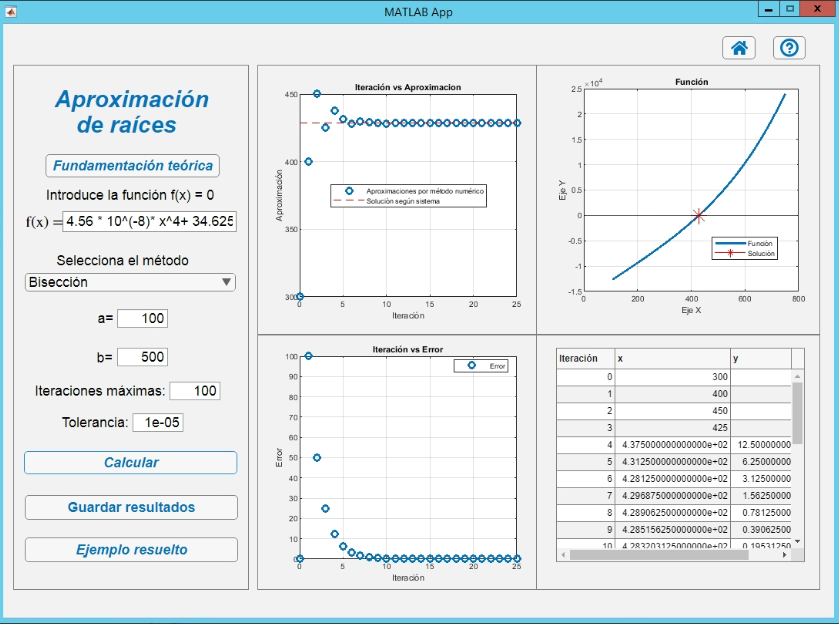

A continuación se muestran los gráficos que brindan la información:

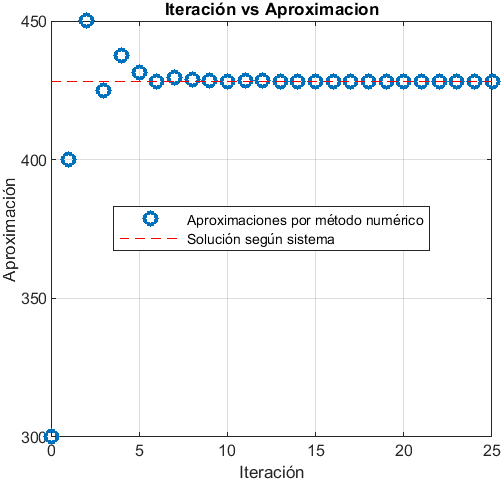

A partir de la información representada en este gráfico se puede observar que basta con realizar 25 iteraciones del método para que se cumpla la condición de error ingresasa (tolerancia). En este caso se visualiza que conforme aumentaban las iteraciones, las aproximaciones iban oscilando (aumentando y disminyendo), sin embargo, convergiendo a un valor específico, por lo que en este caso el método de Bisección converge a la solución del problema. 

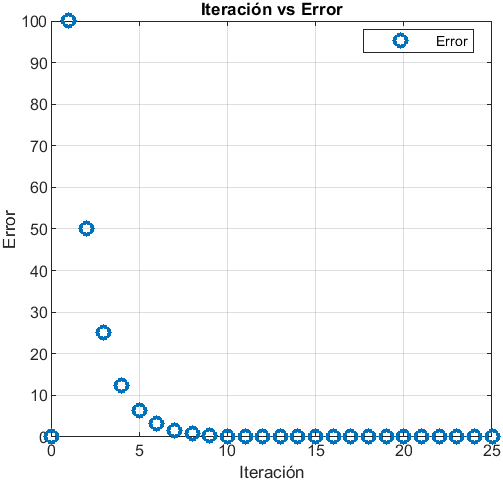

Además, conforme aumentaban las iteraciones del método, se observa como el error iba disminuyendo. Esto afirma que efectivamente el método se acercaba a un valor específico el cual corresponde a la solución del problema.

A continuación se muestra la tabla de datos generada:

format longG
Iteracion=[0;1;2;3;4;5;6;7;8;9;10;11;12;13;14;15;16;17;18;19;20;21;22;23;24;25];
Aproximacion=[300;400;450;425;437.5;431.25;428.125;429.6875;428.90625;428.515625;428.3203125;428.41796875;428.369140625;428.3447265625;428.35693359375;428.350830078125;428.347778320313;428.349304199219;428.350067138672;428.349685668945;428.349876403809;428.349781036377;428.349828720093;428.349804878235;428.349816799164;428.349810838699];
Error=[0;100;50;25;12.5;6.25;3.125;1.5625;0.78125;0.390625;0.1953125;0.09765625;0.048828125;0.0244140625;0.01220703125;0.006103515625;0.0030517578125;0.00152587890625;0.000762939453125;0.0003814697265625;0.00019073486328125;9.5367431640625e-05;4.76837158203125e-05;2.38418579101563e-05;1.19209289550781e-05;5.96046447753906e-06];
T=table(Iteracion, Aproximacion, Error)

T = 26×3 table
    Iteracion      Aproximacion          Error     
    _________    ________________    ______________

        0                     300                 0
        1                     400               100
        2                     450                50
        3                     425                25
        4                   437.5              12.5
        5                  431.25              6.25
        6                 428.125             3.125
        7                429.6875            1.5625
        8               428.90625           0.78125
        9              428.515625          0.390625
       10             428.3203125         0.1953125
       11            428.41796875        0.09765625
       12           428.369140625       0.048828125
       13          428.3447265625      0.0244140625
       14         428.35693359375     0.0122070312

#### Método de la Recta Secante

- Al seleccionar el método de "Recta Secante" y dar clic en el botón "Calcular" la pantalla se visualiza de la siguiente manera:

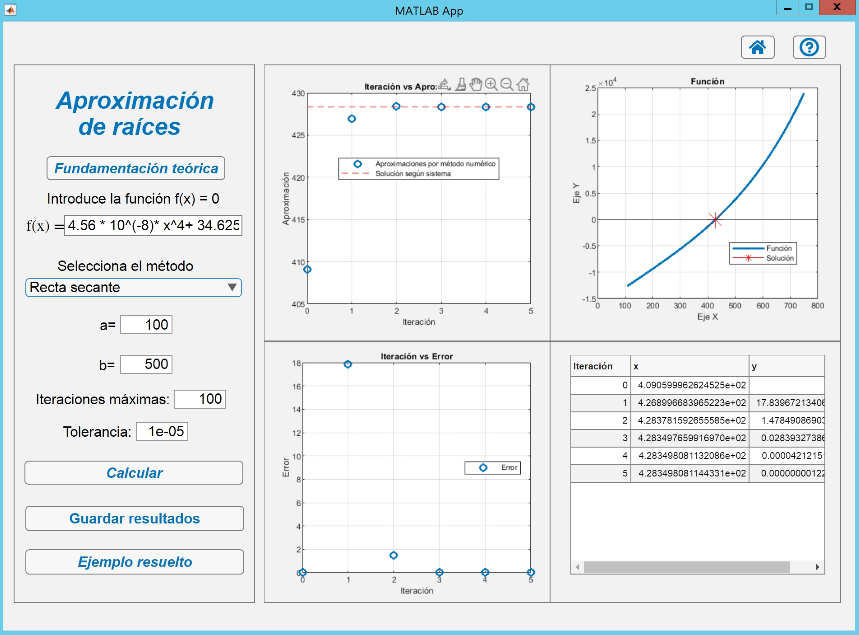

A continuación se muesran los gráificos que brindan la información:

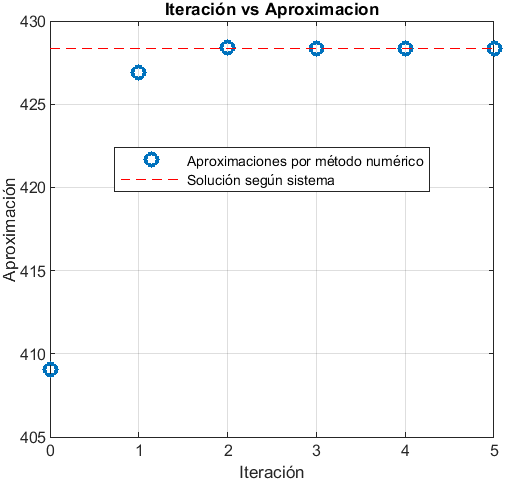

A partir de la información representada en este gráfico se puede observar que basta con realizar 5 iteraciones del método para que se cumpla la condición de error ingresasa (tolerancia). En este caso se visualiza que conforme aumentaban las iteraciones, las aproximaciones se acercaban (aumentando), a un valor específico, por lo que en este caso el método de Recta Secante converge a la solución del problema.

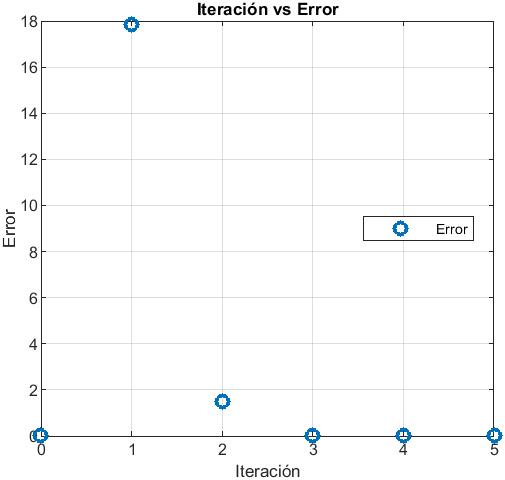

Además, conforme aumentaban las iteraciones del método, se observa como el error iba disminuyendo. Esto afirma que efectivamente el método se acercaba a un valor específico el cual corresponde a la solución del problema.

A continuación se muestra la tabla de datos generada:

format longG
Iteracion=[0;1;2;3;4;5];
Aproximacion=[409.059996262453;426.899668396522;428.378159265558;428.349765991697;428.349808113209;428.349808114433];
Error=[0;17.8396721340698;1.47849086903619;0.0283932738614681;4.21215116261919e-05;1.22452092909953e-09];
Trecta=table(Iteracion, Aproximacion, Error)

Trecta = 6×3 table
    Iteracion      Aproximacion             Error        
    _________    ________________    ____________________

        0        409.059996262453                       0
        1        426.899668396522        17.8396721340698
        2        428.378159265558        1.47849086903619
        3        428.349765991697      0.0283932738614681
        4        428.349808113209    4.21215116261919e-05
        5        428.349808114433    1.22452092909953e-09


#### Método de Falsa Posición

- Al seleccionar el método de "Falsa Posición" y dar clic en el botón "Calcular" la pantalla se visualiza de la siguiente manera:

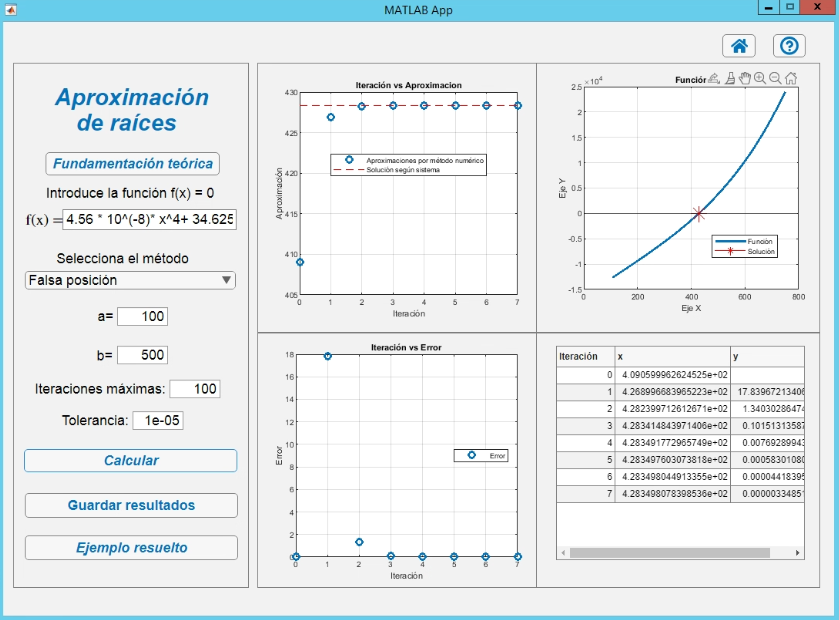

A continuación se muesran los gráificos que brindan la información:

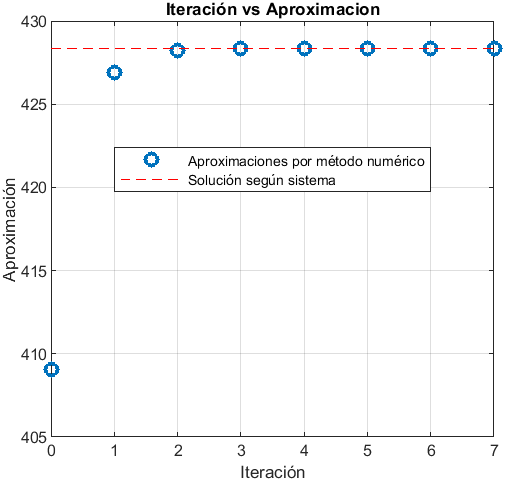

A partir de la información representada en este gráfico se puede observar que basta con realizar 7 iteraciones del método para que se cumpla la condición de error ingresasa (tolerancia). En este caso se visualiza que conforme aumentaban las iteraciones, las aproximaciones se acercaban (aumentando) a un valor específico, por lo que en este caso el método de Falsa Posición converge a la solución del problema.

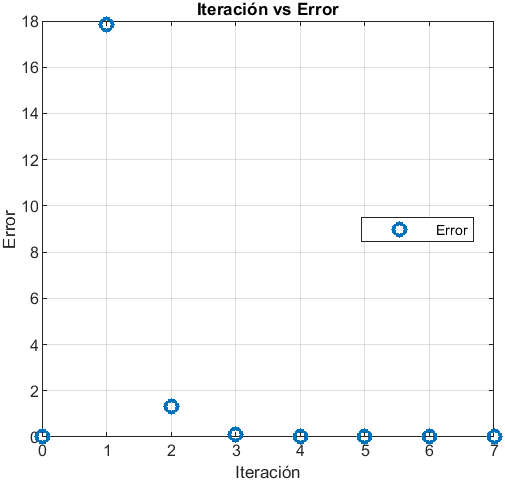

Además, conforme aumentaban las iteraciones del método, se observa como el error iba disminuyendo. Esto afirma que efectivamente el método se acercaba a un valor específico el cual corresponde a la solución del problema.

A continuación se muestra la tabla de datos generada:

format longG
Iteracion=[0;1;2;3;4;5;6;7];
Aproximacion=[409.059996262453;426.899668396522;428.239971261267;428.341484397141;428.349177296575;428.349760307382;428.349804491335;428.349807839854];
Error=[0;17.8396721340698;1.34030286474484;0.101513135873461;0.0076928994342893;0.000583010806963102;4.41839536620137e-05;3.34851807792802e-06];
T2=table(Iteracion, Aproximacion, Error)

T2 = 8×3 table
    Iteracion      Aproximacion             Error        
    _________    ________________    ____________________

        0        409.059996262453                       0
        1        426.899668396522        17.8396721340698
        2        428.239971261267        1.34030286474484
        3        428.341484397141       0.101513135873461
        4        428.349177296575      0.0076928994342893
        5        428.349760307382    0.000583010806963102
        6        428.349804491335    4.41839536620137e-05
        7        428.349807839854    3.34851807792802e-06


#### Método de Newton Raphson

- Al seleccionar el método de "Newton Raphson" y dar clic en el botón "Calcular" la pantalla se visualiza de la siguiente manera:

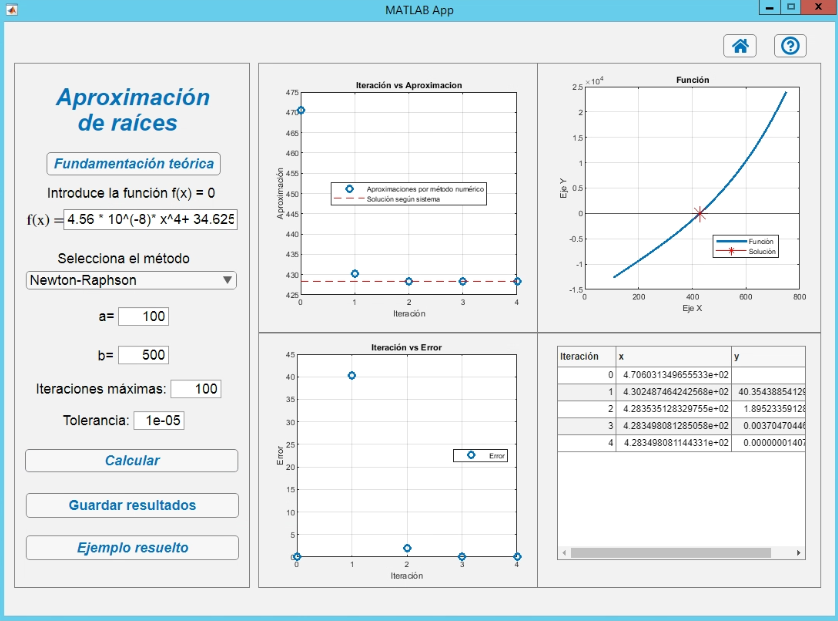

A continuación se muesran los gráificos que brindan la información:

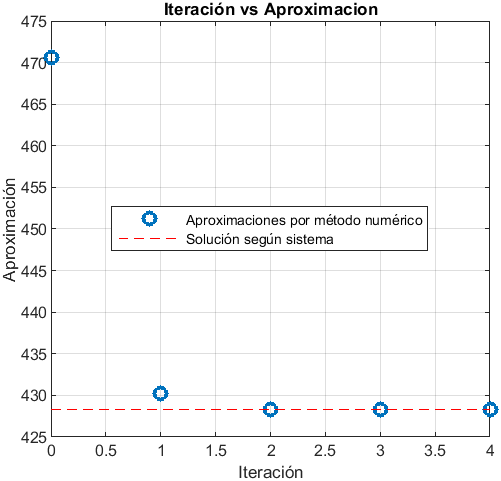

A partir de la información representada en este gráfico se puede observar que basta con realizar 4 iteraciones del método para que se cumpla la condición de error ingresasa (tolerancia). En este caso se visualiza que conforme aumentaban las iteraciones, las aproximaciones se acercaban (disminuyendo) a un valor específico, por lo que en este caso el método de Newton Raphson converge a la solución del problema.

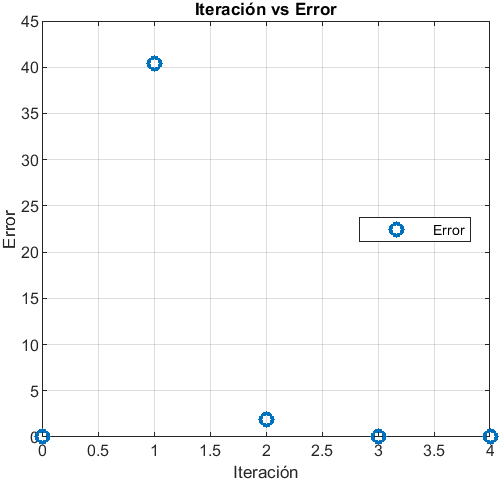

Además, conforme aumentaban las iteraciones del método, se observa como el error iba disminuyendo. Esto afirma que efectivamente el método se acercaba a un valor específico el cual corresponde a la solución del problema.

A continuación se muestra la tabla de datos generada:

format longG
Iteracion=[0;1;2;3;4];
Aproximacion=[470.603134965553;430.248746424257;428.353512832976;428.349808128506;428.349808114433];
Error=[0;40.3543885412965;1.89523359128123;0.00370470446972604;1.40727252073702e-08];
T3=table(Iteracion, Aproximacion, Error)

T3 = 5×3 table
    Iteracion      Aproximacion             Error        
    _________    ________________    ____________________

        0        470.603134965553                       0
        1        430.248746424257        40.3543885412965
        2        428.353512832976        1.89523359128123
        3        428.349808128506     0.00370470446972604
        4        428.349808114433    1.40727252073702e-08


#### Método de Punto Fijo

- Al seleccionar el método de "Punto Fijo" y dar clic en el botón "Calcular" la pantalla se visualiza de la siguiente manera:

*Tome en cuenta que para este método se ha tenido que considerar una función $g$ distinta ya que debe responde a la ecuación $g\left(x\right)=x$, de esta manera:


$$4,56{\times 10}^{-8} x^4 +34,625x-16366,79156=0$$



$$-4,56{\times 10}^{-8} x^4 +16366,79156=34,625x$$



$$\frac{-4,56{\times 10}^{-8} }{34,625}x^4 +\frac{16366,79156}{34,625}=x$$



$$g\left(x\right)=\frac{-4,56{\times 10}^{-8} }{34,625}x^4 +\frac{16366,79156}{34,625}$$


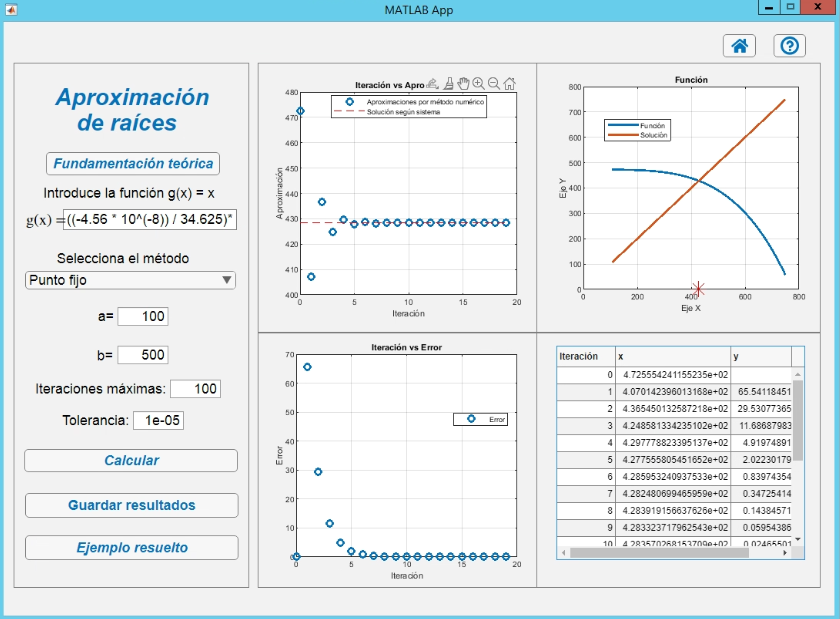

A continuación se muesran los gráificos que brindan la información:

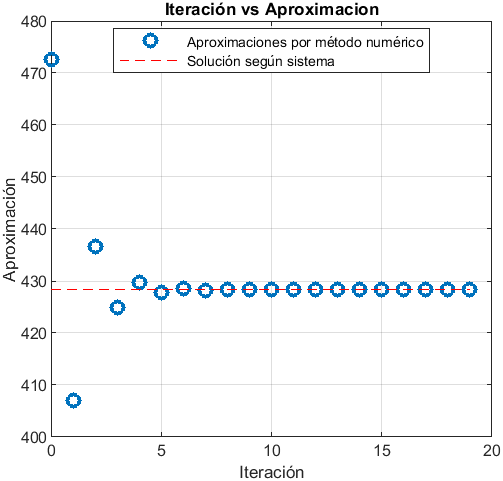

A partir de la información representada en este gráfico se puede observar que basta con realizar 19 iteraciones del método para que se cumpla la condición de error ingresasa (tolerancia). En este caso se visualiza que conforme aumentaban las iteraciones, las aproximaciones iban oscilando (aumentando y disminyendo), sin embargo, convergiendo a un valor específico, por lo que en este caso el método de Punto Fijo converge a la solución del problema. 

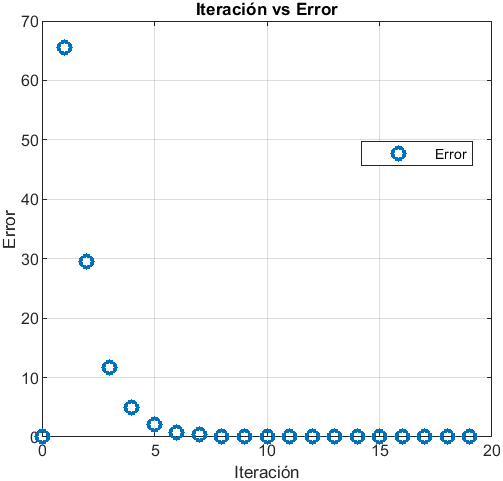

Además, conforme aumentaban las iteraciones del método, se observa como el error iba disminuyendo. Esto afirma que efectivamente el método se acercaba a un valor específico el cual corresponde a la solución del problema.

A continuación se muestra la tabla de datos generada:

format longG
Iteracion=[0;1;2;3;4;5;6;7;8;9;10;11;12;13;14;15;16;17;18;19];
Aproximacion=[472.555424115523;407.014239601317;436.545013258722;424.85813342351;429.777882339514;427.755580545165;428.595324093753;428.248069946596;428.391915663763;428.332371796254;428.357026815371;428.34681928721;428.351045562686;428.349295772726;428.350020238387;428.349720288895;428.349844476743;428.34979305938;428.349814347662;428.349805533695];
Error=[0;65.5411845142067;29.530773657405;11.6868798352116;4.91974891600347;2.02230179434849;0.83974354858816;0.347254147157457;0.143845717166698;0.0595438675082391;0.0246550191166079;0.0102075281604925;0.00422627547516186;0.00174978995920583;0.000724465660482565;0.000299949491648022;0.000124187847973189;5.14173636361193e-05;5.14173636361193e-05;8.81396630347808e-06];
T4=table(Iteracion, Aproximacion, Error)

T4 = 20×3 table
    Iteracion      Aproximacion             Error        
    _________    ________________    ____________________

        0        472.555424115523                       0
        1        407.014239601317        65.5411845142067
        2        436.545013258722         29.530773657405
        3         424.85813342351        11.6868798352116
        4        429.777882339514        4.91974891600347
        5        427.755580545165        2.02230179434849
        6        428.595324093753        0.83974354858816
        7        428.248069946596       0.347254147157457
        8        428.391915663763       0.143845717166698
        9        428.332371796254      0.0595438675082391
       10        428.357026815371      0.0246550191166079
       11         428.34681928721      0.0102075281604925
       12        428.351045562686     0.00422627547516186
       13  

#### Comparación de resultados

A continuación se brinda una tabla resumen de los datos obtenudos con cada uno de los métodos:

Metodo=["Bisección";"Recta Secante";"Falsa Posición";"Newton Raphson";"Punto Fijo"];
Iteracion=[25;5;7;4;19];
Aproximacion=[428.349810838699;428.349808114433;428.349807839854;3.34851807792802e-06;428.349805533695];
Error=[5.96046447753906e-06;1.22452092909953e-09;3.34851807792802e-06;1.40727252073702e-08;8.81396630347808e-06];
T5=table(Metodo,Iteracion,Aproximacion,Error)

T5 = 5×4 table
         Metodo         Iteracion        Aproximacion               Error        
    ________________    _________    ____________________    ____________________

    "Bisección"            25            428.349810838699    5.96046447753906e-06
    "Recta Secante"         5            428.349808114433    1.22452092909953e-09
    "Falsa Posición"        7            428.349807839854    3.34851807792802e-06
    "Newton Raphson"        4        3.34851807792802e-06    1.40727252073702e-08
    "Punto Fijo"           19            428.349805533695    8.81396630347808e-06


### Ejercicios propuestos

- Considere la función $f\left(x\right)=x-2^{-x}$. Demuestre que dicha función tiene una raíz en el intervalo $\left\lbrack 0,1\right\rbrack$ y usando el método de bisección, aproxime dicha raíz con un error menor que ${10}^{-5}$.

- Realice tres iteraciones del método de la recta secante para hallar una aproximación del cero de la función $f\left(x\right)=\sqrt{x}-\cos \left(x\right)$ usando como primeras aproximaciones $x_0 =0$ y $x_1 =1$. Compare con la solución obtenida mediante el método de bisección.

- Con el método de Newton Raphson resueva la ecuación $0=\frac{1}{2}+\frac{1}{4}x^2 -x\;\sin \left(x\right)-\frac{1}{2}\cos \left(2x\right)$ usando $p_0 =\frac{\pi }{4}$. Itere hasta que el error sea menor a ${10}^{-3}$. Repita el ejercicio usando como valor inicial $p_0 =\frac{\pi }{2}$.

-  Considere la función $g\left(x\right)=\sqrt{\sin \left(x\right)+1}\ldotp$ Demuestre que $g$ tiene un punto fijo en $\left\lbrack 0,2\right\rbrack$ y verifique que el método de punto fijo converge a dicho elemento. Aplique cuatro iteraciones del método de punto fijo para aproximar este. Utilice como punto inicial $x_0 =1$ y calcule el error que se obtiene en esta aproximación.

- Cuando se trata de encontrar la acidez de una solución de hidróxido de magnesio en ácido clorhídrico, se obtiene la siguiente ecuación:


$$A\left(x\right)=x^3 +3\ldotp 5x^2 -40$$


            donde $x$ es la concentración de iones hidronio. Encontrar la concentración de iones hidronio de una solución saturada (nota: una solución se dice saturada si la acidez es igual cero). Escoja para cada método el o los valores iniciales enteros más     cercanos posibles y compare los resultados obtenidos (número de interacciones, precisión de las aproximaciones obtenidas).

### Referencias

- Burden, A., Burden, R. y Faires, J. (2017). *Análisis Numérico* (10a ed.). México. Grupo Editorial Iberoamérica.

- Chapra, S.C. y Canale, R. (2007). M*étodos numéricos para Ingenieros* (5a ed.). México. Editorial MacGraw-Hill.

- Chavarría, J. (2014). *Métodos numéricos*. Editorial Tecnológica de Costa Rica.